clear
clc

% Die MATLAB Deep Learning Toolbox stellt einige Funktionen zum Arbeiten mit
% tiefen neuronalen Netzen zur Verfügung.

baseFolder = "C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt";
cd(baseFolder)

datenFolder = baseFolder + "\09_Trainingsdaten\AusgeschnittenFürTraining\99_Trainingsdatensätze\01_3Kat30_ohne_30empfehlung";

imdsSchilder = imageDatastore(datenFolder, ...
    "IncludeSubfolders", true, ...
    "LabelSource", "foldernames");

countEachLabel(imdsSchilder)

ans = 3×2 table
                Label                Count
    _____________________________    _____

    BilderOhneSchilder                408 
    Geschwindigkeitsbegrenzung_30     402 
    Geschwindigkeitsempfehlung_30     591 



numPerLabel = min(countEachLabel(imdsSchilder).Count);
allLabels = unique(imdsSchilder.Labels);
classNames = categories(imdsSchilder.Labels);

numRuns = 10;

% Ergebnisvariablen für Excel-Ausgabe
RunNr = zeros(numRuns,1);
TrainAccuracy = zeros(numRuns,1);
ValidationAccuracy = zeros(numRuns,1);
GesamtAccuracy = zeros(numRuns,1);
AnzahlFalschTrain = zeros(numRuns,1);
AnzahlFalschValidation = zeros(numRuns,1);
AnzahlFalschGesamt = zeros(numRuns,1);

for run = 1:numRuns

    fprintf("\n=====================================\n");
    fprintf("START LAUF %d von %d\n", run, numRuns);
    fprintf("=====================================\n");

    % Jeder Lauf bekommt anderen, aber reproduzierbaren Zufall
    rng(run, "twister")

    %% Balancing neu erzeugen
    balancedFiles = [];

    for i = 1:numel(allLabels)
        label = allLabels(i);

        idx = find(imdsSchilder.Labels == label);

        if numel(idx) >= numPerLabel
            selectedIdx = randsample(idx, numPerLabel);
            balancedFiles = [balancedFiles; imdsSchilder.Files(selectedIdx)];
        else
            warning("Label '%s' hat weniger als %d Bilder.", string(label), numPerLabel);
        end
    end

    % Neuen ImageDatastore mit ausgewählten Dateien erstellen
    balancedDS = imageDatastore(balancedFiles, ...
        'Labels', categorical(cellstr(extractBetween(balancedFiles, ...
        fullfile(datenFolder, '\'), filesep))));

    %% Train-/Validation-Split neu erzeugen
    [imdsTrain, imdsValidation] = splitEachLabel(balancedDS, 0.8, "randomized");

    %% Netzwerk definieren
    % GAP-Variante
    layers = [
        imageInputLayer([48, 48, 3], "Name", "input", "Normalization", "none")

        convolution2dLayer(3, 8, 'Padding', 'same', "Name", "conv_1")
        reluLayer("Name", "relu_1")
        maxPooling2dLayer(2, 'Stride', 2, "Name", "maxpool_1")

        convolution2dLayer(3, 16, 'Padding', 'same', "Name", "conv_2")
        reluLayer("Name", "relu_2")
        maxPooling2dLayer(2, 'Stride', 2, "Name", "maxpool_2")

        fullyConnectedLayer(3, "Name", "fc") 
        softmaxLayer("Name", "softmax")
    ];

    %% Augmented Datastores
    augTrain = augmentedImageDatastore([48 48 3], imdsTrain, ...
        'ColorPreprocessing', 'none', ...
        'OutputSizeMode', 'resize');

    augVal = augmentedImageDatastore([48 48 3], imdsValidation, ...
        'ColorPreprocessing', 'none', ...
        'OutputSizeMode', 'resize');

    aug2 = augmentedImageDatastore([48 48 3], imdsSchilder, ...
        'ColorPreprocessing', 'none', ...
        'OutputSizeMode', 'resize');

    %% Trainingsparameter
    options = trainingOptions('adam', ...
        'MaxEpochs', 50, ...
        "InitialLearnRate", 0.0005, ...
        'MiniBatchSize', 16, ...
        'Shuffle', 'every-epoch', ...
        Plots="training-progress", ...
        Metrics="accuracy", ...
        ValidationData=augVal, ...
        ValidationFrequency=60, ...
        Verbose=true, ...
    VerboseFrequency=50);

    %% Training
    fprintf("Training Lauf %d startet...\n", run);

    [net, info] = trainnet(augTrain, layers, "crossentropy", options);
    T = info.TrainingHistory;
    writetable(T, sprintf("TrainingHistoryFC_Lauf_%02d.xlsx", run));
    % Netz und Trainingsinfo je Lauf speichern
    % save(sprintf("netGAP_Lauf_%02d.mat", run), "net", "info");

    fprintf("Training Lauf %d beendet.\n", run);

    %% Schätzung Trainingsdatensatz
    tbl = readall(augTrain);
    imgs = tbl{:,1};

    TTrain = imdsTrain.Labels;
    classNamesTrain = categories(TTrain);

    XTrain = cat(4, imgs{:});
    XTrain = single(XTrain);

    outputsTrain = minibatchpredict(net, XTrain);
    YTrain = onehotdecode(squeeze(outputsTrain), classNamesTrain, 2);

    fig = figure("Name", sprintf("Lauf %02d - Confusion Training", run));
    confusionchart(TTrain, YTrain);
    title(sprintf("Lauf %02d - Training", run));

    confMatTrain = confusionmat(TTrain, YTrain);
    accuracyTrain = sum(diag(confMatTrain)) / sum(confMatTrain(:));
    fprintf('Lauf %d - Training Accuracy: %.2f%%\n', run, accuracyTrain * 100);

    %% Schätzung Validierungsdatensatz
    tbl = readall(augVal);
    imgs = tbl{:,1};

    TTest = imdsValidation.Labels;
    classNamesTest = categories(TTest);

    XTest = cat(4, imgs{:});
    XTest = single(XTest);

    outputsTest = minibatchpredict(net, XTest);
    YTest = onehotdecode(squeeze(outputsTest), classNamesTest, 2);

    fig = figure("Name", sprintf("Lauf %02d - Confusion Validation", run));
    confusionchart(TTest, YTest);
    title(sprintf("Lauf %02d - Validation", run));

    confMatVal = confusionmat(TTest, YTest);
    accuracyVal = sum(diag(confMatVal)) / sum(confMatVal(:));
    fprintf('Lauf %d - Validation Accuracy: %.2f%%\n', run, accuracyVal * 100);

    %% Schätzung Gesamtbestand
    tbl = readall(aug2);
    imgs = tbl{:,1};

    TTest2 = imdsSchilder.Labels;

    XTest2 = cat(4, imgs{:});
    XTest2 = single(XTest2);

    outputsTest2 = minibatchpredict(net, XTest2);
    YTest2 = onehotdecode(squeeze(outputsTest2), classNames, 2);

    fig = figure("Name", sprintf("Lauf %02d - Confusion Gesamtbestand", run));
    confusionchart(TTest2, YTest2);
    title(sprintf("Lauf %02d - Gesamtbestand", run));

    confMatAll = confusionmat(TTest2, YTest2);
    accuracyAll = sum(diag(confMatAll)) / sum(confMatAll(:));
    fprintf('Lauf %d - Gesamt Accuracy: %.2f%%\n', run, accuracyAll * 100);

    %% Falsche Ergebnisse ausgeben
    trueLabelsTrain = imdsTrain.Labels;
    trueLabelsVali = imdsValidation.Labels;
    trueLabelsVali2 = imdsSchilder.Labels;

    wrongIdxtrain = find(YTrain ~= trueLabelsTrain);
    wrongIdxVali = find(YTest ~= trueLabelsVali);
    wrongIdxVali2 = find(YTest2 ~= trueLabelsVali2);

    fprintf("Lauf %d - Falsch Training: %d\n", run, numel(wrongIdxtrain));
    fprintf("Lauf %d - Falsch Validation: %d\n", run, numel(wrongIdxVali));
    fprintf("Lauf %d - Falsch Gesamtbestand: %d\n", run, numel(wrongIdxVali2));

## ** Falsch erkannte bilder anzeigen**

START LAUF 1 von 10


Training Lauf 1 startet...


    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss    ValidationLoss    TrainingAccuracy    ValidationAccuracy
    _________    _____    ___________    _________    ____________    ______________    ________________    __________________
            0        0       00:00:00       0.0005                            10.234                                     33.75
            1        1       00:00:00       0.0005          9.2373                                  37.5                      
           50        1       00:00:03       0.0005          3.8622                                 68.75                      
           60        1       00:00:04       0.0005          1.8033            2.0392               81.25                80.417
          100        2       00:00:05       0.0005          1.6038                                  87.5                      
          120        2       00:00:06       0.0005         0.36419            1.4239                87.5       

Training Lauf 1 beendet.


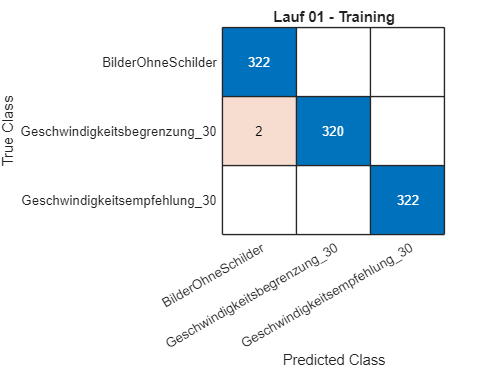

Lauf 1 - Training Accuracy: 99.79%


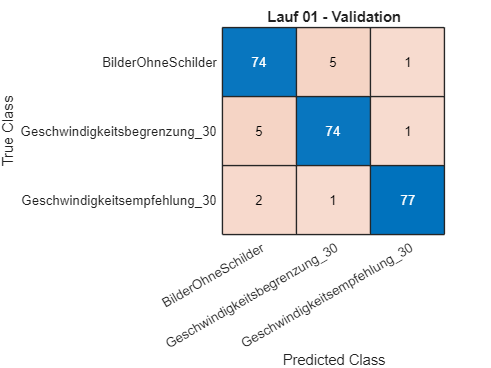

Lauf 1 - Validation Accuracy: 93.75%


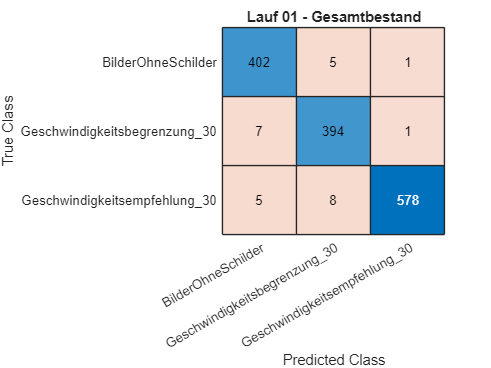

Lauf 1 - Gesamt Accuracy: 98.07%


Lauf 1 - Falsch Training: 2


Lauf 1 - Falsch Validation: 15


Lauf 1 - Falsch Gesamtbestand: 27


    Lauf    TrainingAccuracy    ValidationAccuracy    GesamtAccuracy    FalschTraining    FalschValidation    FalschGesamt
    ____    ________________    __________________    ______________    ______________    ________________    ____________

     1           99.793               93.75               98.073              2                  15                27     



ENDE LAUF 1 von 10


START LAUF 2 von 10


Training Lauf 2 startet...


    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss    ValidationLoss    TrainingAccuracy    ValidationAccuracy
    _________    _____    ___________    _________    ____________    ______________    ________________    __________________
            0        0       00:00:00       0.0005                            10.836                                    31.667
            1        1       00:00:02       0.0005           10.96                                 31.25                      
           50        1       00:00:05       0.0005          2.9448                                 68.75                      
           60        1       00:00:05       0.0005          4.4109            1.8841               56.25                77.917
          100        2       00:00:06       0.0005          1.2099                                  87.5                      
          120        2       00:00:07       0.0005          1.2905            1.1792               81.25       

Training Lauf 2 beendet.


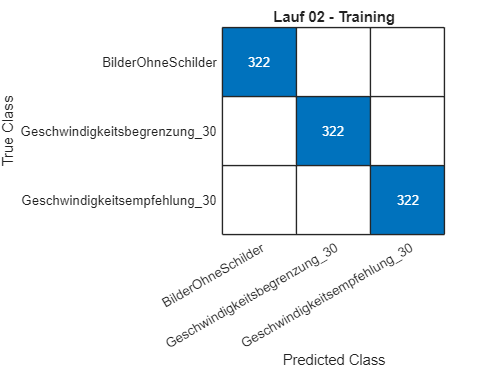

Lauf 2 - Training Accuracy: 100.00%


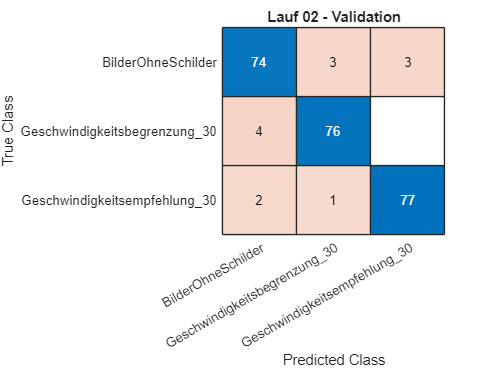

Lauf 2 - Validation Accuracy: 94.58%


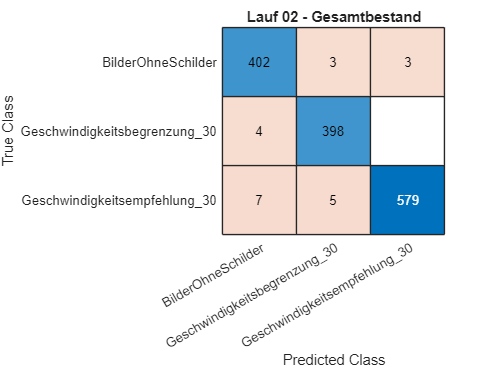

Lauf 2 - Gesamt Accuracy: 98.43%


Lauf 2 - Falsch Training: 0


Lauf 2 - Falsch Validation: 13


Lauf 2 - Falsch Gesamtbestand: 22


    Lauf    TrainingAccuracy    ValidationAccuracy    GesamtAccuracy    FalschTraining    FalschValidation    FalschGesamt
    ____    ________________    __________________    ______________    ______________    ________________    ____________

     1           99.793                93.75              98.073              2                  15                27     
     2              100               94.583               98.43              0                  13                22     



ENDE LAUF 2 von 10


START LAUF 3 von 10


Training Lauf 3 startet...


    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss    ValidationLoss    TrainingAccuracy    ValidationAccuracy
    _________    _____    ___________    _________    ____________    ______________    ________________    __________________
            0        0       00:00:00       0.0005                            10.521                                    32.083
            1        1       00:00:01       0.0005           11.31                                    25                      
           50        1       00:00:04       0.0005          2.1885                                 81.25                      
           60        1       00:00:04       0.0005         0.96482            1.8216               81.25                82.083
          100        2       00:00:06       0.0005         0.39388                                 93.75                      
          120        2       00:00:07       0.0005          0.9965           0.92537               93.75       

Training Lauf 3 beendet.


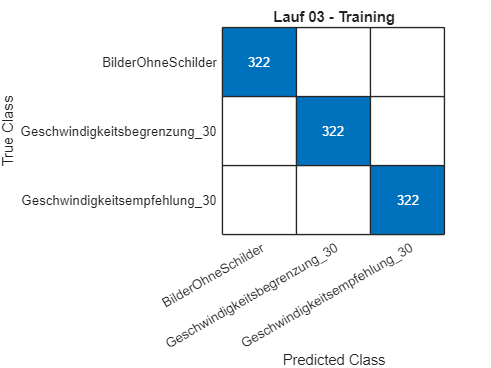

Lauf 3 - Training Accuracy: 100.00%


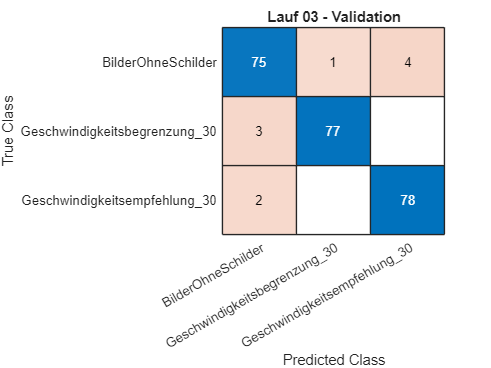

Lauf 3 - Validation Accuracy: 95.83%


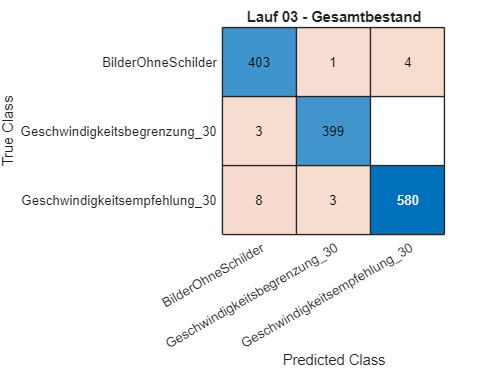

Lauf 3 - Gesamt Accuracy: 98.64%


Lauf 3 - Falsch Training: 0


Lauf 3 - Falsch Validation: 10


Lauf 3 - Falsch Gesamtbestand: 19


    Lauf    TrainingAccuracy    ValidationAccuracy    GesamtAccuracy    FalschTraining    FalschValidation    FalschGesamt
    ____    ________________    __________________    ______________    ______________    ________________    ____________

     1           99.793                93.75              98.073              2                  15                27     
     2              100               94.583               98.43              0                  13                22     
     3              100               95.833              98.644              0                  10                19     



ENDE LAUF 3 von 10


START LAUF 4 von 10


Training Lauf 4 startet...


    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss    ValidationLoss    TrainingAccuracy    ValidationAccuracy
    _________    _____    ___________    _________    ____________    ______________    ________________    __________________
            0        0       00:00:00       0.0005                            10.628                                    33.333
            1        1       00:00:00       0.0005           13.95                                  12.5                      
           50        1       00:00:04       0.0005          1.0897                                    75                      
           60        1       00:00:04       0.0005          1.2152             1.573                87.5                80.417
          100        2       00:00:05       0.0005         0.53186                                 93.75                      
          120        2       00:00:06       0.0005          1.0066            1.2815               81.25       

Training Lauf 4 beendet.


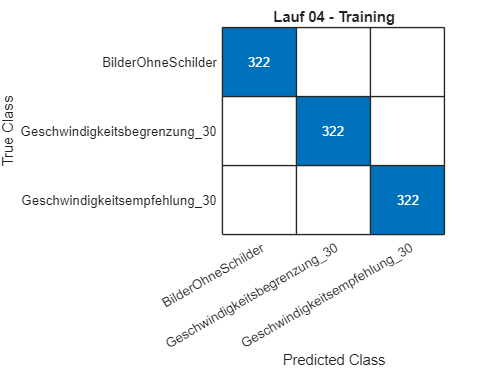

Lauf 4 - Training Accuracy: 100.00%


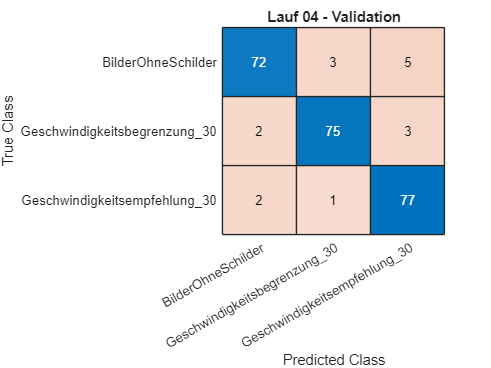

Lauf 4 - Validation Accuracy: 93.33%


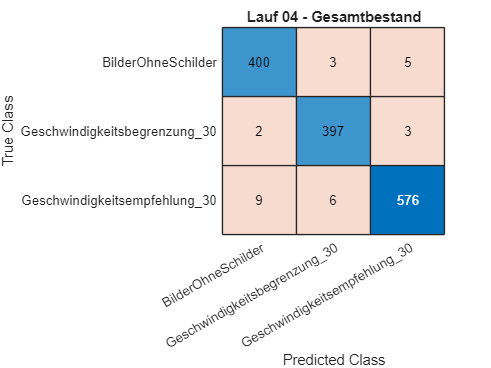

Lauf 4 - Gesamt Accuracy: 98.00%


Lauf 4 - Falsch Training: 0


Lauf 4 - Falsch Validation: 16


Lauf 4 - Falsch Gesamtbestand: 28


    Lauf    TrainingAccuracy    ValidationAccuracy    GesamtAccuracy    FalschTraining    FalschValidation    FalschGesamt
    ____    ________________    __________________    ______________    ______________    ________________    ____________

     1           99.793                93.75              98.073              2                  15                27     
     2              100               94.583               98.43              0                  13                22     
     3              100               95.833              98.644              0                  10                19     
     4              100               93.333              98.001              0                  16                28     



ENDE LAUF 4 von 10


START LAUF 5 von 10


Training Lauf 5 startet...


    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss    ValidationLoss    TrainingAccuracy    ValidationAccuracy
    _________    _____    ___________    _________    ____________    ______________    ________________    __________________
            0        0       00:00:00       0.0005                            9.4081                                    29.167
            1        1       00:00:00       0.0005          6.7548                                  37.5                      
           50        1       00:00:03       0.0005          3.3285                                 68.75                      
           60        1       00:00:04       0.0005           1.683            3.1806               68.75                    70
          100        2       00:00:05       0.0005          1.4731                                  87.5                      
          120        2       00:00:06       0.0005          1.2529            1.5415                  75       

Training Lauf 5 beendet.


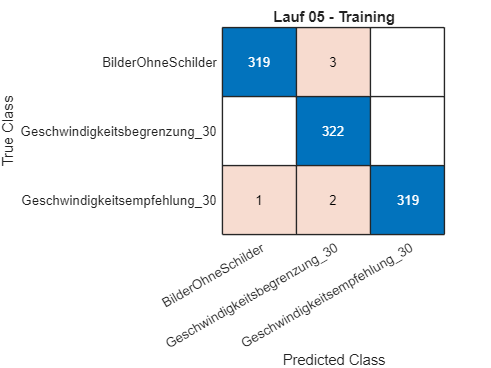

Lauf 5 - Training Accuracy: 99.38%


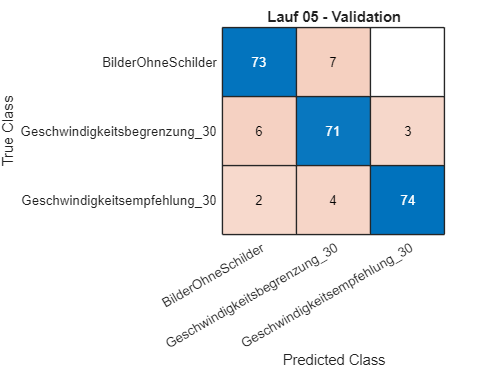

Lauf 5 - Validation Accuracy: 90.83%


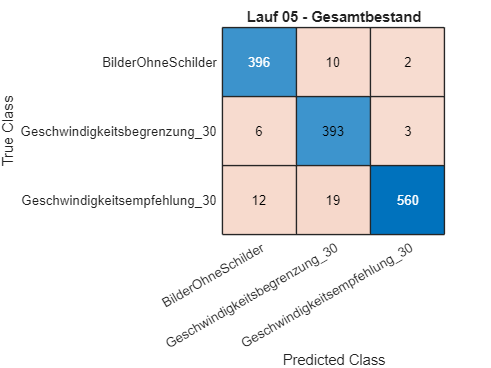

Lauf 5 - Gesamt Accuracy: 96.29%


Lauf 5 - Falsch Training: 6


Lauf 5 - Falsch Validation: 22


Lauf 5 - Falsch Gesamtbestand: 52


    Lauf    TrainingAccuracy    ValidationAccuracy    GesamtAccuracy    FalschTraining    FalschValidation    FalschGesamt
    ____    ________________    __________________    ______________    ______________    ________________    ____________

     1           99.793                93.75              98.073              2                  15                27     
     2              100               94.583               98.43              0                  13                22     
     3              100               95.833              98.644              0                  10                19     
     4              100               93.333              98.001              0                  16                28     
     5           99.379

ENDE LAUF 5 von 10


START LAUF 6 von 10


Training Lauf 6 startet...


    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss    ValidationLoss    TrainingAccuracy    ValidationAccuracy
    _________    _____    ___________    _________    ____________    ______________    ________________    __________________
            0        0       00:00:00       0.0005                            6.4845                                     51.25
            1        1       00:00:00       0.0005          5.9784                                  62.5                      
           50        1       00:00:03       0.0005          1.8764                                    75                      
           60        1       00:00:04       0.0005          2.0621             2.101               81.25                80.833
          100        2       00:00:05       0.0005      0.00067217                                   100                      
          120        2       00:00:06       0.0005            2.49            1.7247               81.25       

Training Lauf 6 beendet.


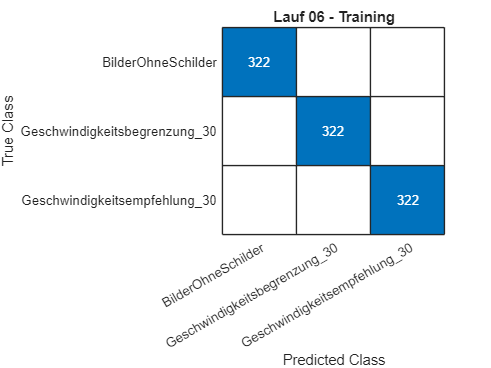

Lauf 6 - Training Accuracy: 100.00%


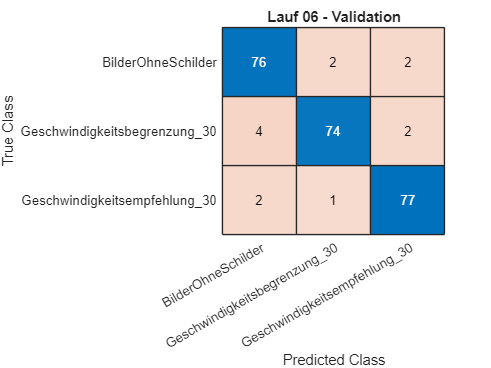

Lauf 6 - Validation Accuracy: 94.58%


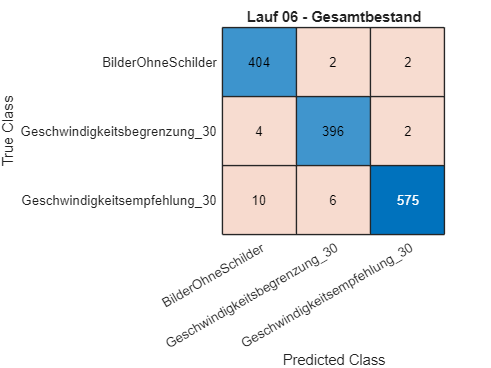

Lauf 6 - Gesamt Accuracy: 98.14%


Lauf 6 - Falsch Training: 0


Lauf 6 - Falsch Validation: 13


Lauf 6 - Falsch Gesamtbestand: 26


    Lauf    TrainingAccuracy    ValidationAccuracy    GesamtAccuracy    FalschTraining    FalschValidation    FalschGesamt
    ____    ________________    __________________    ______________    ______________    ________________    ____________

     1           99.793                93.75              98.073              2                  15                27     
     2              100               94.583               98.43              0                  13                22     
     3              100               95.833              98.644              0                  10                19     
     4              100               93.333              98.001              0                  16                28     
     5           99.379

ENDE LAUF 6 von 10


START LAUF 7 von 10


Training Lauf 7 startet...


    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss    ValidationLoss    TrainingAccuracy    ValidationAccuracy
    _________    _____    ___________    _________    ____________    ______________    ________________    __________________
            0        0       00:00:00       0.0005                            10.609                                        30
            1        1       00:00:00       0.0005          12.914                                  12.5                      
           50        1       00:00:03       0.0005          2.1372                                 81.25                      
           60        1       00:00:04       0.0005          1.9628            2.3981               81.25                75.833
          100        2       00:00:05       0.0005         0.10113                                 93.75                      
          120        2       00:00:06       0.0005          0.9964            1.7642               93.75       

Training Lauf 7 beendet.


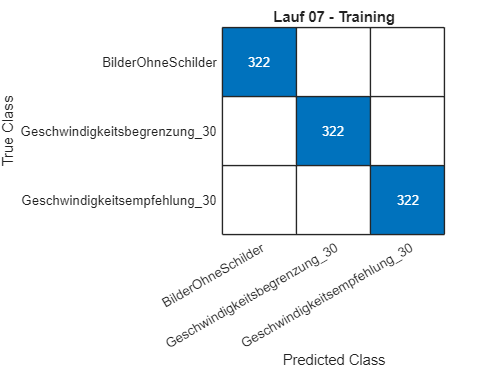

Lauf 7 - Training Accuracy: 100.00%


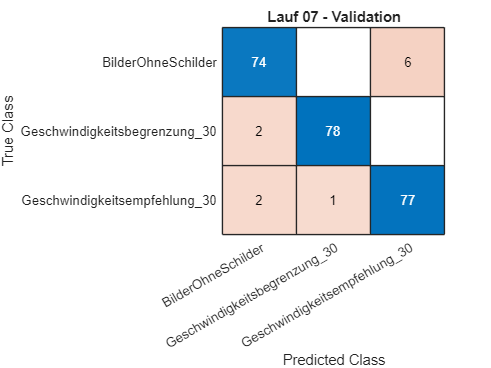

Lauf 7 - Validation Accuracy: 95.42%


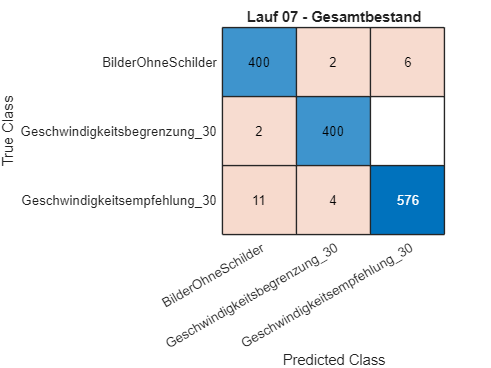

Lauf 7 - Gesamt Accuracy: 98.22%


Lauf 7 - Falsch Training: 0


Lauf 7 - Falsch Validation: 11


Lauf 7 - Falsch Gesamtbestand: 25


    Lauf    TrainingAccuracy    ValidationAccuracy    GesamtAccuracy    FalschTraining    FalschValidation    FalschGesamt
    ____    ________________    __________________    ______________    ______________    ________________    ____________

     1           99.793                93.75              98.073              2                  15                27     
     2              100               94.583               98.43              0                  13                22     
     3              100               95.833              98.644              0                  10                19     
     4              100               93.333              98.001              0                  16                28     
     5           99.379

ENDE LAUF 7 von 10


START LAUF 8 von 10


Training Lauf 8 startet...


    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss    ValidationLoss    TrainingAccuracy    ValidationAccuracy
    _________    _____    ___________    _________    ____________    ______________    ________________    __________________
            0        0       00:00:00       0.0005                            10.187                                    32.917
            1        1       00:00:00       0.0005          10.102                                 31.25                      
           50        1       00:00:03       0.0005          2.0356                                    75                      
           60        1       00:00:04       0.0005          1.5869            1.3184               68.75                84.167
          100        2       00:00:05       0.0005         0.79145                                 93.75                      
          120        2       00:00:06       0.0005          1.4136           0.73604                87.5       

Training Lauf 8 beendet.


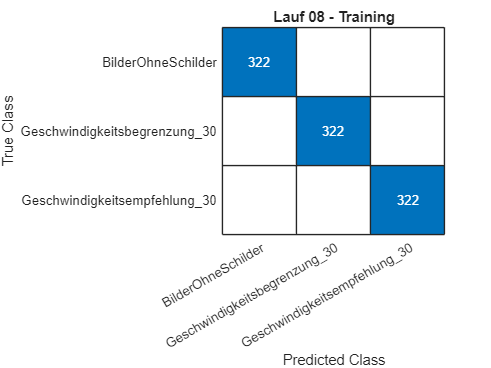

Lauf 8 - Training Accuracy: 100.00%


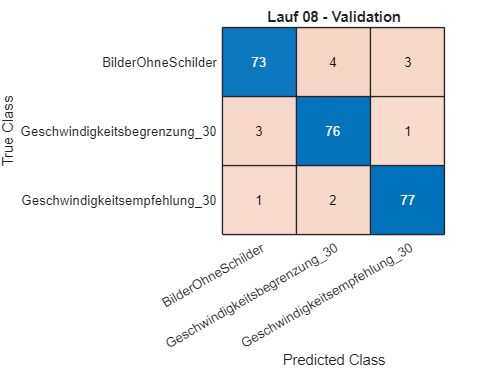

Lauf 8 - Validation Accuracy: 94.17%


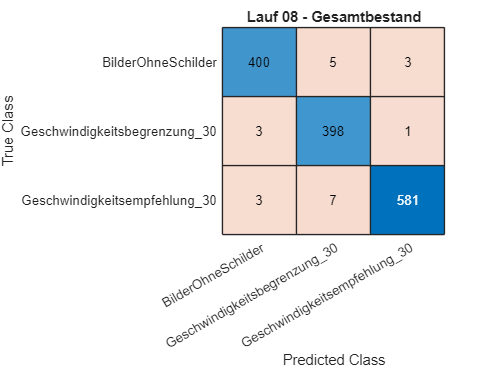

Lauf 8 - Gesamt Accuracy: 98.43%


Lauf 8 - Falsch Training: 0


Lauf 8 - Falsch Validation: 14


Lauf 8 - Falsch Gesamtbestand: 22


    Lauf    TrainingAccuracy    ValidationAccuracy    GesamtAccuracy    FalschTraining    FalschValidation    FalschGesamt
    ____    ________________    __________________    ______________    ______________    ________________    ____________

     1           99.793                93.75              98.073              2                  15                27     
     2              100               94.583               98.43              0                  13                22     
     3              100               95.833              98.644              0                  10                19     
     4              100               93.333              98.001              0                  16                28     
     5           99.379

ENDE LAUF 8 von 10


START LAUF 9 von 10


Training Lauf 9 startet...


    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss    ValidationLoss    TrainingAccuracy    ValidationAccuracy
    _________    _____    ___________    _________    ____________    ______________    ________________    __________________
            0        0       00:00:00       0.0005                            10.628                                    33.333
            1        1       00:00:00       0.0005          12.953                                 18.75                      
           50        1       00:00:04       0.0005          3.2417                                 68.75                      
           60        1       00:00:04       0.0005          2.9536            2.9937               68.75                69.167
          100        2       00:00:06       0.0005          1.4846                                 81.25                      
          120        2       00:00:06       0.0005        0.097271            1.3964               93.75       

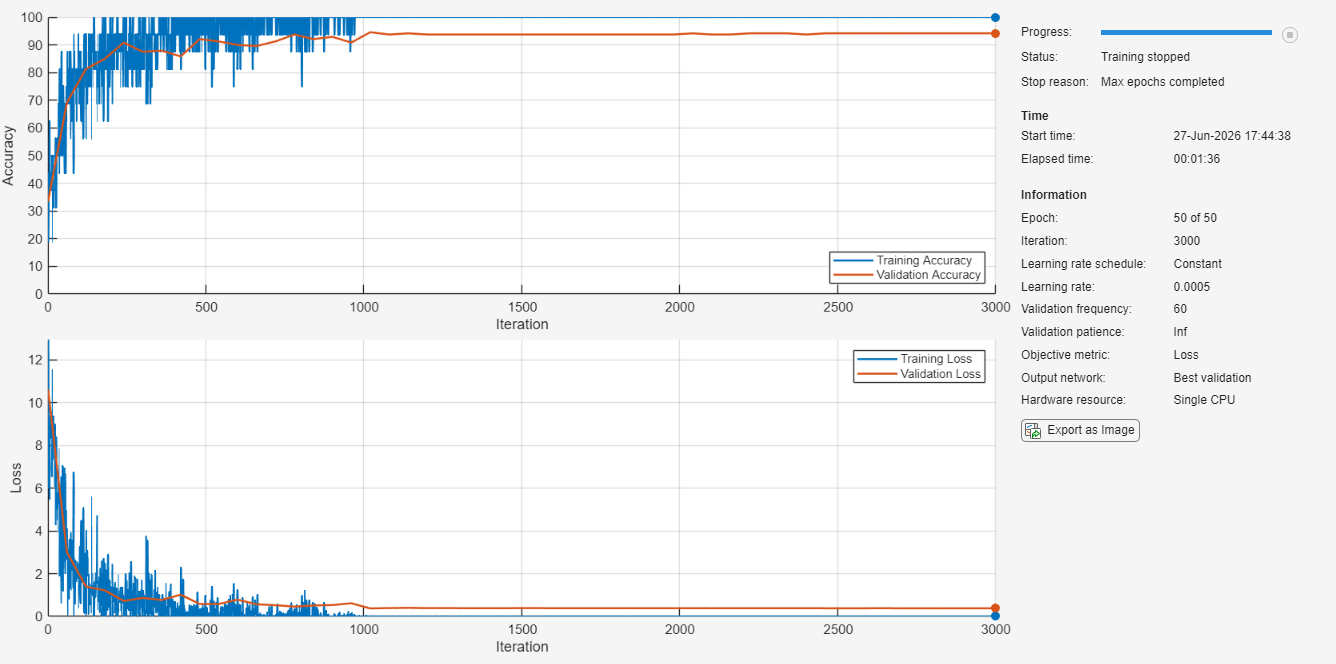

Training Lauf 9 beendet.


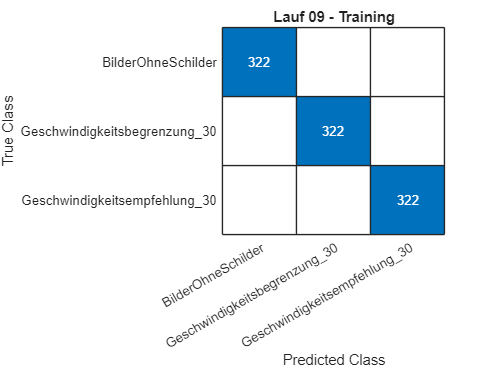

Lauf 9 - Training Accuracy: 100.00%


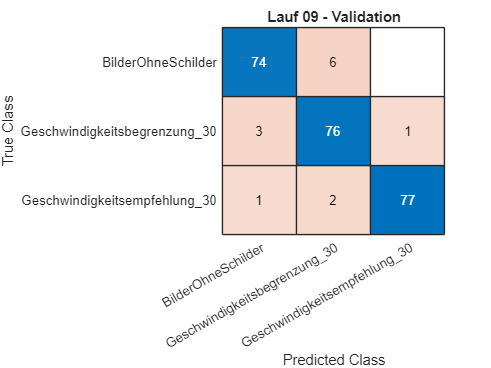

Lauf 9 - Validation Accuracy: 94.58%


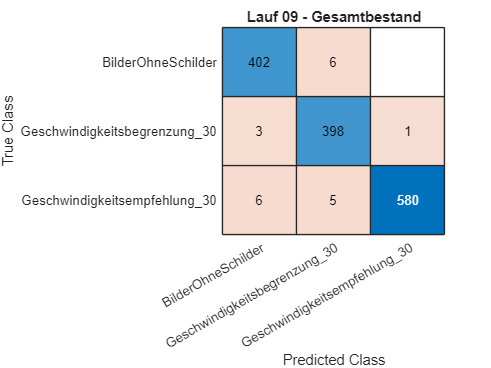

Lauf 9 - Gesamt Accuracy: 98.50%


Lauf 9 - Falsch Training: 0


Lauf 9 - Falsch Validation: 13


Lauf 9 - Falsch Gesamtbestand: 21


    Lauf    TrainingAccuracy    ValidationAccuracy    GesamtAccuracy    FalschTraining    FalschValidation    FalschGesamt
    ____    ________________    __________________    ______________    ______________    ________________    ____________

     1           99.793                93.75              98.073              2                  15                27     
     2              100               94.583               98.43              0                  13                22     
     3              100               95.833              98.644              0                  10                19     
     4              100               93.333              98.001              0                  16                28     
     5           99.379

ENDE LAUF 9 von 10


START LAUF 10 von 10


Training Lauf 10 startet...


    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss    ValidationLoss    TrainingAccuracy    ValidationAccuracy
    _________    _____    ___________    _________    ____________    ______________    ________________    __________________
            0        0       00:00:00       0.0005                            8.6165                                    35.833
            1        1       00:00:00       0.0005          9.2943                                  37.5                      
           50        1       00:00:04       0.0005          2.7906                                 43.75                      
           60        1       00:00:04       0.0005          1.0403            1.4435               68.75                  77.5
          100        2       00:00:05       0.0005         0.50394                                 93.75                      
          120        2       00:00:06       0.0005         0.20878           0.71701               93.75       

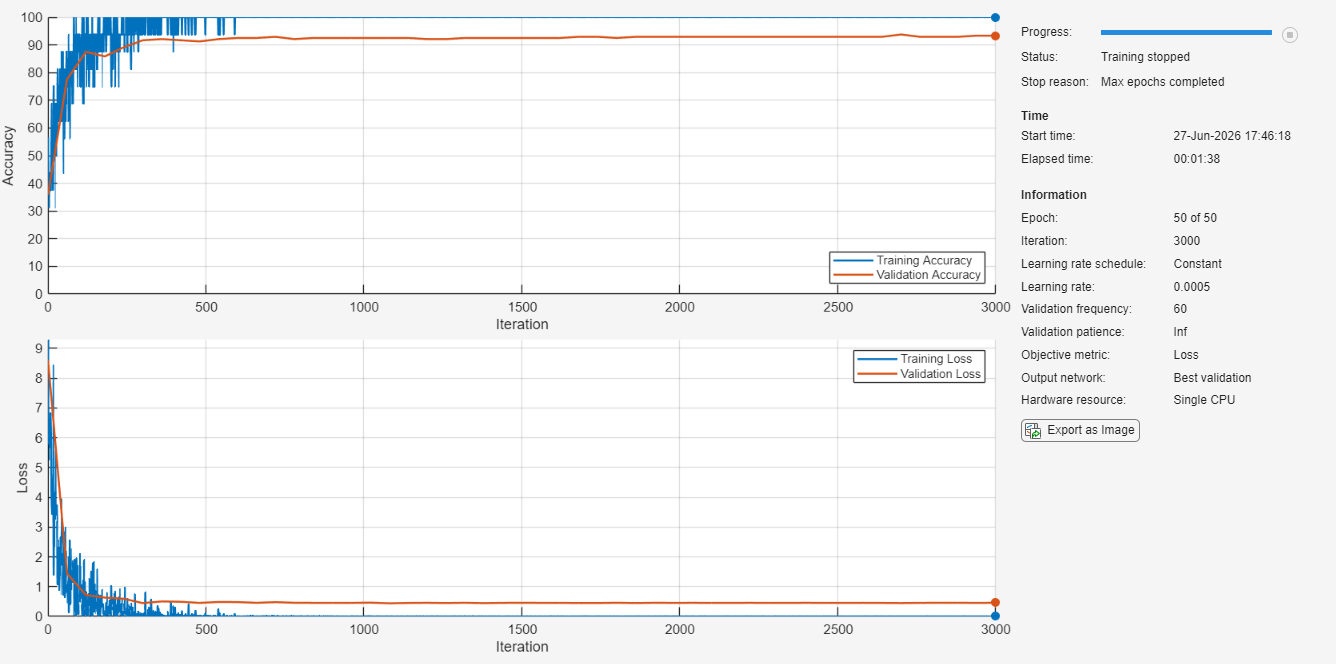

Training Lauf 10 beendet.


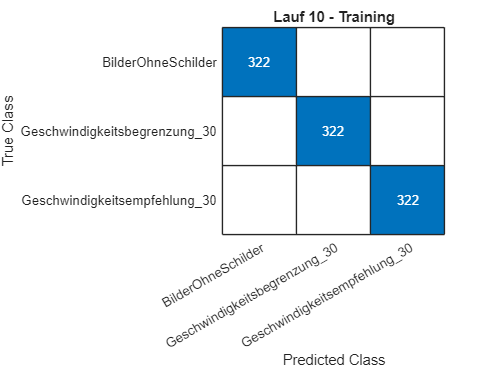

Lauf 10 - Training Accuracy: 100.00%


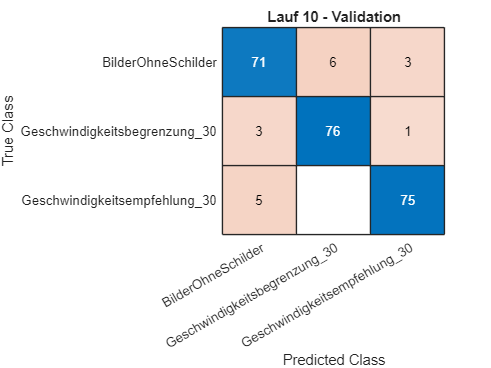

Lauf 10 - Validation Accuracy: 92.50%


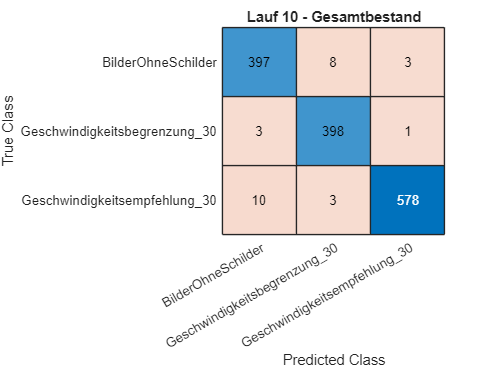

Lauf 10 - Gesamt Accuracy: 98.00%


Lauf 10 - Falsch Training: 0


Lauf 10 - Falsch Validation: 18


Lauf 10 - Falsch Gesamtbestand: 28


    Lauf    TrainingAccuracy    ValidationAccuracy    GesamtAccuracy    FalschTraining    FalschValidation    FalschGesamt
    ____    ________________    __________________    ______________    ______________    ________________    ____________

      1          99.793                93.75              98.073              2                  15                27     
      2             100               94.583               98.43              0                  13                22     
      3             100               95.833              98.644              0                  10                19     
      4             100               93.333              98.001              0                  16                28     
      5          99.379

ENDE LAUF 10 von 10


    % % Falsch erkannte Trainingsbilder anzeigen
    % for i = 1:length(wrongIdxtrain)
    %     img = readimage(imdsTrain, wrongIdxtrain(i));
    %     figure("Name", sprintf("Lauf %02d - Training falsch %03d", run, i));
    %     imshow(img);
    %     title(sprintf("Lauf %02d Training falsch: Vorhersage = %s, Richtig = %s", ...
    %         run, string(YTrain(wrongIdxtrain(i))), string(trueLabelsTrain(wrongIdxtrain(i)))));
    % end
    % 
    % for i = 1:length(wrongIdxVali)
    %     img = readimage(imdsValidation, wrongIdxVali(i));
    %     figure("Name", sprintf("Lauf %02d - Validation falsch %03d", run, i));
    %     imshow(img);
    %     title(sprintf("Lauf %02d Validation falsch: Vorhersage = %s, Richtig = %s", ...
    %         run, string(YTest(wrongIdxVali(i))), string(trueLabelsVali(wrongIdxVali(i)))));
    % end
    % 
    % % Dateinamen der falsch erkannten Gesamtbilder speichern
    % dateiname = imdsSchilder.Files(wrongIdxVali2);
    % 
    % wrongTable = table( ...
    %     repmat(run, numel(wrongIdxVali2), 1), ...
    %     string(dateiname), ...
    %     string(trueLabelsVali2(wrongIdxVali2)), ...
    %     string(YTest2(wrongIdxVali2)), ...
    %     'VariableNames', ["Lauf", "Dateiname", "RichtigesLabel", "Vorhersage"]);
    % 
    % writetable(wrongTable, sprintf("Falsch_Gesamtbestand_Lauf_%02d.csv", run));

    %% Werte dieses Laufs speichern
    RunNr(run) = run;
    TrainAccuracy(run) = accuracyTrain * 100;
    ValidationAccuracy(run) = accuracyVal * 100;
    GesamtAccuracy(run) = accuracyAll * 100;
    AnzahlFalschTrain(run) = numel(wrongIdxtrain);
    AnzahlFalschValidation(run) = numel(wrongIdxVali);
    AnzahlFalschGesamt(run) = numel(wrongIdxVali2);

    results = table(RunNr(1:run), ...
        TrainAccuracy(1:run), ...
        ValidationAccuracy(1:run), ...
        GesamtAccuracy(1:run), ...
        AnzahlFalschTrain(1:run), ...
        AnzahlFalschValidation(1:run), ...
        AnzahlFalschGesamt(1:run), ...
        'VariableNames', ["Lauf", "TrainingAccuracy", "ValidationAccuracy", ...
        "GesamtAccuracy", "FalschTraining", "FalschValidation", "FalschGesamt"]);

    % disp(results)

    % Nach jedem Lauf direkt schreiben, damit nichts verloren geht
    writetable(results, "GAP_Ergebnisse_Einzellaeufe.csv");

    fprintf("ENDE LAUF %d von %d\n", run, numRuns);

end


fprintf("\nAlle Läufe beendet.\n");


Alle Läufe beendet.


disp(results)

    Lauf    TrainingAccuracy    ValidationAccuracy    GesamtAccuracy    FalschTraining    FalschValidation    FalschGesamt
    ____    ________________    __________________    ______________    ______________    ________________    ____________

      1          99.793                93.75              98.073              2                  15                27     
      2             100               94.583               98.43              0                  13                22     
      3             100               95.833              98.644              0                  10                19     
      4             100               93.333              98.001              0                  16                28     
      5          99.379